# Configuration Space: Part 2 of 2

## **INTRODUCTION**

In the previous part of the assignment, you implemented an algorithm to check if two triangles intersect with each other at any point. Since, the robotic arm and the obstacles are a group of triangles, the means to check if a configuration is viable or not becomes indispensable.

For Week 1 homework assignment you were asked to complete the function `DijkstraGrid` which was used to plan paths through simple grid based environments, modeled using 2D logical arrays. In the following part of the assignment you are going to extend that idea by completing the function `DijkstraTorus`.

`DijkstraTorus` takes in the configuration space, as derived from the triangle intersections between the robotic arm and the obstacles in the workspace, and implements the Dijkstra's algorithm to calculate the shortest feasible route from a starting configuration to the ending configuration.

## **IMPLEMENTATION**

The input and output arguments for this function are explained below:

- `input_map`: a logical array where the freespace cells are false or 0 and the obstacles are true or 1.

- `start_coords, dest_coords`: Coordinates of the start and end cell respectively, the first entry is the row and the second the column.

- `route`: An array containing the linear indices of the cells along the shortest route from start to dest or an empty array if there is no route.

Note: 

- The particular function contains a variable `label` which gives you the choice of whether you wish to see the output of the function or not.

- The following code uses an existing version of `triangle_intersection.m `as it is crucial in the implementation of `DijkstraTorus`. If you wish to apply your version of the code, plug in your code in the `triangle_intersection.m `provided in the MATLAB zip File link provided below .

- For simplicity and reduction of computation time, an existing configuration space has already been loaded. The code to create this configuration space is mentioned in `TwoLinkCspace.m` in the MATLAB zip file link below.

- If you wish to see the animation of how your code works, download the MATLAB zip file from the summary window in the previous screen and plug in your code

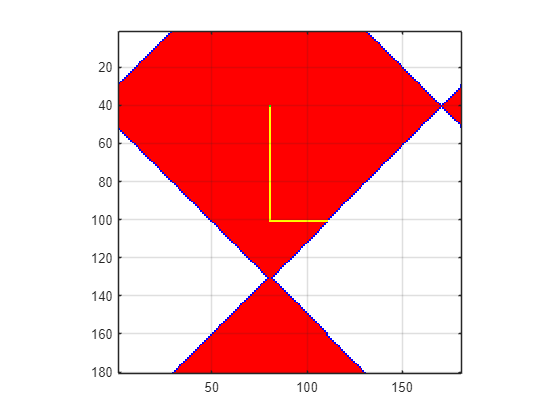

theta1_range = 0:2:360;
theta2_range = 0:2:360;

nrows = length(theta2_range);
ncols = length(theta1_range);

cspace = false(nrows, ncols);

start_coords = [40, 80];
end_coords = [100, 110];
route = DijkstraTorus (cspace, start_coords, end_coords);

function route = DijkstraTorus (input_map, start_coords, dest_coords)
    % Run Dijkstra's algorithm on a grid.
    % Inputs : 
    %   input_map : a logical array where the freespace cells are false or 0 and
    %      the obstacles are true or 1
    %   start_coords and dest_coords : Coordinates of the start and end cell
    %       respectively, the first entry is the row and the second the column.
    % Output :
    %   route : An array containing the linear indices of the cells along the
    %    shortest route from start to dest or an empty array if there is no
    %    route.
    
    % set up color map for display
    % 1 - white - clear cell
    % 2 - black - obstacle
    % 3 - red = visited
    % 4 - blue  - on list
    % 5 - green - start
    % 6 - yellow - destination
    
    cmap = [1 1 1; ...
            0 0 0; ...
            1 0 0; ...
            0 0 1; ...
            0 1 0; ...
            1 1 0];
    
    colormap(cmap);
    
    label = true;
    
    input_map(:, 181) = [];
    
    input_map(181, :) = [];
    
    [nrows, ncols] = size(input_map);
    
    % map - a table that keeps track of the state of each grid cell
    map = zeros(nrows,ncols);
    
    map(~input_map) = 1;  % Mark free cells
    map(input_map)  = 2;  % Mark obstacle cells
    
    % Generate linear indices of start and dest nodes
    start_node = sub2ind(size(map), start_coords(1), start_coords(2));
    dest_node  = sub2ind(size(map), dest_coords(1),  dest_coords(2));
    
    map(start_node) = 5;
    map(dest_node)  = 6;
    
    % Initialize distance array
    distances = Inf(nrows,ncols);
    
    % For each grid cell this array holds the index of its parent
    parent = zeros(nrows,ncols);
    
    distances(start_node) = 0;
    
    % Main Loop
    while true
        % Draw current map
        map(start_node) = 5;
        map(dest_node) = 6;
        
        % image(1.5, 1.5, map);
        % grid on;
        % axis image;
        % drawnow;
  
        % Find the node with the minimum distance
        [min_dist, current] = min(distances(:));
        
        if ((current == dest_node) || isinf(min_dist))
            break;
        end;
        
        % Update map
        map(current) = 3;         % mark current node as visited
        distances(current) = Inf; % remove this node from further consideration
        
        % Compute row, column coordinates of current node
        [i, j] = ind2sub(size(distances), current);
        
        % Visit each neighbor of the current node and update the map, distances
        % and parent tables appropriately.
       
        %%% All of your code should be between the two lines of stars. 
        % *******************************************************************
        ii=0;
        jj=0;

        if (i>1 && i<=nrows)
            ii = i-1;
            jj = j;
            update(ii, jj, min_dist+1, current);
        end

        if i<=1
            ii = nrows;
            jj = j;
            update(ii, jj, min_dist+1, current);
        end

        if (i>=1 && i<nrows)
            ii = i+1;
            jj = j;
            update(ii, jj, min_dist+1, current);
        end

        if i>=nrows
            ii = 1;
            jj = j;
            update(ii, jj, min_dist+1, current);
        end

        if (j>1 && j<=ncols)
            jj = j-1;
            ii = i;
            update(ii, jj, min_dist+1, current);
        end

        if j<=1
            ii = i;
            jj = ncols;
            update(ii, jj, min_dist+1, current);
        end

        if (j>=1 && j<ncols)
            jj = j+1;
            ii = i;
            update(ii, jj, min_dist+1, current);
        end

        if j>=ncols
            ii = i;
            jj = 1;
            update(ii, jj, min_dist+1, current);
        end
        % *******************************************************************
    end
    
    if (isinf(distances(dest_node)))
        route = [];
    else
        route = [dest_node];
        
        while (parent(route(1)) ~= 0)
            route = [parent(route(1)), route];
        end

        drawMap(label);
    end
    
    function update (i, j, d, p)
        if ((map(i, j) ~= 2) && (map(i, j) ~= 3) && (map(i, j) ~= 5) && (distances(i, j) > d))
            distances(i, j) = d;
            map(i, j) = 4;
            parent(i, j) = p;
        end
    end

    function drawMap(label)
        if label==true
            for k = 2:length(route) - 1        
                map(route(k)) = 7;
            end

            image(1.5, 1.5, map);
            grid on;
            axis image;
        end
     end
end